# Robot Arm Rotation Angles

This code defines `fx` and `fy` as functions of   and  .

syms theta1 theta2
fx(theta1,theta2) = 2*cos(theta1+theta2) + 4*cos(theta1)

$$fx(theta1, theta2) = 2\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)$$

fy(theta1,theta2) = 2*sin(theta1+theta2) + 4*sin(theta1)

$$fy(theta1, theta2) = 2\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)$$

## Task 1

The x and y coordinates of the robot's end effector are defined in the script as symbolic functions `fx` and `fy`, which depend on the rotation angles `theta1` and `theta2`.

Task

Find the x and y coordinates of the end effector when the first arm is at an angle of pi/8

 radians and the second arm is at an angle of pi/6 radians. Store the results in  `xpos` and `ypos` respectively.

xpos=fx(pi/8,pi/6)

$$xpos = 2\,\cos\left(\frac{7\,\pi }{24}\right)+2\,\sqrt{\sqrt{2}+2}$$

ypos=fy(pi/8,pi/6)

$$ypos = 2\,\sin\left(\frac{7\,\pi }{24}\right)+2\,\sqrt{2-\sqrt{2}}$$

## Task 2

You can use the `double` function to convert symbolic values to numeric values.

`k` `=` `sym``(``1``/``3``)``;`

`c` `=` `cos``(``k``)`

`c` `=`

cos(1/3)

`a` `=` `double``(``c``)`

`a` `=`  

   `0.9450`

Task

Convert the symbolic values in `xpos` and `ypos` to numeric values. Store the results in `xposn` and `yposn`, respectively.

xposn=double(xpos)

xposn = 4.9130

yposn=double(ypos)

yposn = 3.1174

## Task 3

Assume that `theta1` and `theta2` can only be values from 0 to pi.

`assume([theta1 theta2]>0)`

`assumeAlso([theta1 theta2]<=pi)`

`assumptions`

## Task 4

If the desired x-y location of the end effector is (3,5), what angles should the joints be set to?

The `solve` function can be used to solve for `theta1` and `theta2`.

`[``sol1``,``sol2``]` `=` `solve``([``eqn1` `eqn2``]``,``[``var1` `var2``])`

Task

Determine the values of `theta1` and `theta2` that give the position (3,5). Store the results in `theta1sol` and `theta2sol`, respectively.

[theta1sol,theta2sol]=solve([fx==3 fy==5])

$$theta1sol = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\sqrt{15}}{35}+\frac{4}{7}\right)\\ -2\,\mathrm{atan}\left(\frac{\sqrt{15}}{35}-\frac{4}{7}\right) \end{array}\right)$$

$$theta2sol = \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sqrt{15}}{15}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{15}}{15}\right) \end{array}\right)$$

## Further Practice

Try using `double` to see the approximate numeric value for the angles.

`double``(``theta1sol``)`

`double``(``theta2sol``)`

With *θ*1 and *θ*2 limited to 0 to *π*, where can the robot arm reach? In `fsurf`, you can specify the interval for `theta1` and `theta2`.

`fsurf``(``fx``,``fy``,``0``,``[``0` `pi``])`

`view``(``2``)`

`axis` `equal`

double(theta1sol)

ans =     1.1972
    0.8636


double(theta2sol)

ans =    -0.5054
    0.5054


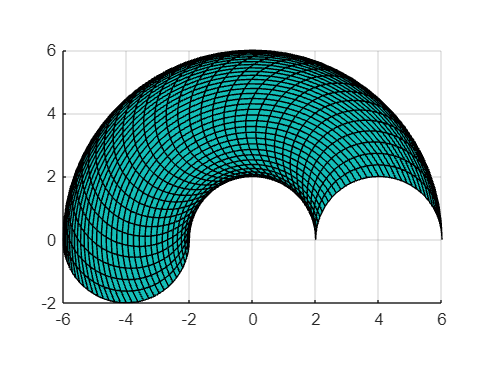

fsurf(fx,fy,0,[0 pi])
view(2)
axis equal

assume([theta1 theta2],"clear")